# Optimización con restricciones no lineales de igualdad usando multiplicadores de Lagrange en MATLAB

**Alumno:** Pablo Ruiz Molina

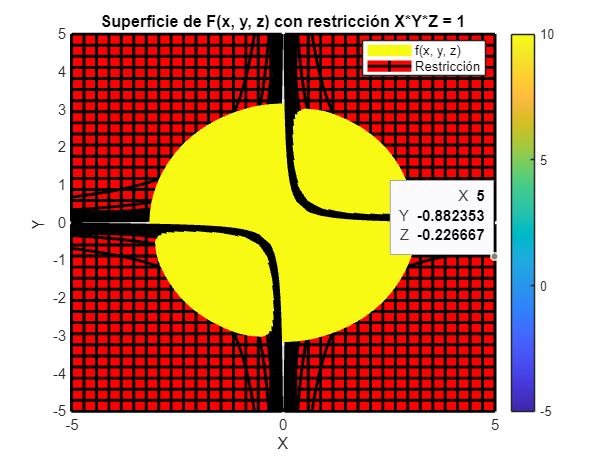

clc; clear; close all;

% Definir el rango de valores para X, Y y Z
x = linspace(-5, 5, 50);
y = linspace(-5, 5, 50);
z = linspace(-5, 5, 50);
[X, Y, Z] = meshgrid(x, y, z);

% Definir la función objetivo F(x, y, z)
F = X.^2 + Y.^2 + Z.^2;

% Graficar la función objetivo en 3D como una isosuperficie
figure;
hold on;
isosurface(X, Y, Z, F, 10); % Isosuperficie de nivel 10
colormap parula;
colorbar;

% Graficar la restricción X*Y*Z = 1
fimplicit3(@(x, y, z) x.*y.*z - 1, [-5, 5, -5, 5, -5, 5], 'r', 'LineWidth', 2);

% Etiquetas y título
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Superficie de F(x, y, z) con restricción X*Y*Z = 1');
legend('f(x, y, z)', 'Restricción', 'Location', 'best');


% xlim([0 500])
% ylim([0 500])
% zlim([-300000 300000])
% view([-33 8])

grid on;
hold off;

## Resolución con multiplicadores de Lagrange

% Limpieza de la consola, variables y figuras
clc; clear; close all;

%% Definir la función objetivo y la restricción
syms x y z lambda;

% Función objetivo
f = x^2 + y^2 + z^2;

% Restricción
g = x*y*z - 1;

%% Definir la función Lagrangiana
L = f + lambda * g;

%% Calcular las derivadas parciales de la Lagrangiana
grad_L_x = diff(L, x);
grad_L_y = diff(L, y);
grad_L_z = diff(L, z);
grad_L_lambda = diff(L, lambda);

%% Resolver el sistema de ecuaciones
% Crear el sistema de ecuaciones igualando las derivadas a cero
eqns = [grad_L_x == 0, grad_L_y == 0, grad_L_z == 0, grad_L_lambda == 0];
vars = [x, y, z, lambda];
solutions = solve(eqns, vars);

% Extraer soluciones
x_solutions = double(solutions.x);
y_solutions = double(solutions.y);
z_solutions = double(solutions.z);
lambda_solutions = double(solutions.lambda);

% Mostrar las soluciones
disp('Puntos críticos:')

Puntos críticos:


for i = 1:length(x_solutions)
    fprintf('x = %.4f, y = %.4f, lambda = %.4f\n', x_solutions(i), y_solutions(i), lambda_solutions(i));
end

x = 1.0000, y = -1.0000, lambda = -2.0000
x = -1.0000, y = 1.0000, lambda = -2.0000
x = -1.0000, y = -1.0000, lambda = -2.0000
x = 1.0000, y = 1.0000, lambda = -2.0000
x = -0.5000, y = -0.5000, lambda = 1.0000
x = 0.5000, y = 0.5000, lambda = 1.0000
x = 0.5000, y = -0.5000, lambda = 1.0000
x = -0.5000, y = 0.5000, lambda = 1.0000
x = 0.5000, y = -0.5000, lambda = 1.0000
x = -0.5000, y = 0.5000, lambda = 1.0000
x = -0.5000, y = -0.5000, lambda = 1.0000
x = 0.5000, y = 0.5000, lambda = 1.0000



%% Evaluar el valor de la función objetivo en los puntos críticos
f_critical = double(subs(f, {x, y, z}, {x_solutions, y_solutions, z_solutions}));

% Mostrar los valores de la función objetivo en los puntos críticos
disp('Valores de la función objetivo en los puntos críticos:')

Valores de la función objetivo en los puntos críticos:


disp(f_critical)

   3.0000 + 0.0000i
   3.0000 + 0.0000i
   3.0000 + 0.0000i
   3.0000 + 0.0000i
  -1.5000 + 2.5981i
  -1.5000 + 2.5981i
  -1.5000 + 2.5981i
  -1.5000 + 2.5981i
  -1.5000 - 2.5981i
  -1.5000 - 2.5981i
  -1.5000 - 2.5981i
  -1.5000 - 2.5981i




%% Calcular el Hessiano Orlado para clasificar los puntos críticos
% Definir el Hessiano de la Lagrangiana con respecto a x e y
H_L = [diff(grad_L_x, x), diff(grad_L_x, y), diff(grad_L_x, z); diff(grad_L_y, x), diff(grad_L_y, y), diff(grad_L_y, z); diff(grad_L_z, x), diff(grad_L_z, y), diff(grad_L_z, z)];

for i = 1:length(x_solutions)
    % Sustituir x, y y lambda en el Hessiano Orlado
    H_L_eval = double(subs(H_L, {x, y, z, lambda}, {x_solutions(i), y_solutions(i), z_solutions(i), lambda_solutions(i)}));
    grad_g = [diff(g, x); diff(g, y); diff(g, z)];
    grad_g_eval = double(subs(grad_g, {x, y, z}, {x_solutions(i), y_solutions(i), z_solutions(i)}));
    
    % Crear el Hessiano Orlado
    H_orlado = [0, grad_g_eval.'; grad_g_eval, H_L_eval];
    
    % Mostrar el Hessiano Orlado
    fprintf('\nHessiano Orlado para el punto crítico (x = %.4f, y = %.4f, z = %.4f):\n', x_solutions(i), y_solutions(i), z_solutions(i));
    disp(H_orlado);
    
    % Calculamos el determinante del Hessiano orlado
    det_H_orlado = det(H_orlado);
    
    % Mostramos el determinante del Hessiano orlado
    disp(['Determinante del Hessiano orlado: ', num2str(det_H_orlado)]);
    
    % Clasificación del punto crítico
    if det_H_orlado < 0
        disp('El punto crítico es un mínimo relativo.');
    elseif det_H_orlado > 0
        disp('El punto crítico es un máximo relativo.');
    else
        disp('El punto crítico es un punto de silla o requiere análisis adicional.');
    end    
end


Hessiano Orlado para el punto crítico (x = 1.0000, y = -1.0000, z = -1.0000):


     0     1    -1    -1
     1     2     2     2
    -1     2     2    -2
    -1     2    -2     2



Determinante del Hessiano orlado: -48


El punto crítico es un mínimo relativo.



Hessiano Orlado para el punto crítico (x = -1.0000, y = 1.0000, z = -1.0000):


     0    -1     1    -1
    -1     2     2    -2
     1     2     2     2
    -1    -2     2     2



Determinante del Hessiano orlado: -48


El punto crítico es un mínimo relativo.



Hessiano Orlado para el punto crítico (x = -1.0000, y = -1.0000, z = 1.0000):


     0    -1    -1     1
    -1     2    -2     2
    -1    -2     2     2
     1     2     2     2



Determinante del Hessiano orlado: -48


El punto crítico es un mínimo relativo.



Hessiano Orlado para el punto crítico (x = 1.0000, y = 1.0000, z = 1.0000):


     0     1     1     1
     1     2    -2    -2
     1    -2     2    -2
     1    -2    -2     2



Determinante del Hessiano orlado: -48


El punto crítico es un mínimo relativo.



Hessiano Orlado para el punto crítico (x = -0.5000, y = -0.5000, z = -0.5000):


   0.0000 + 0.0000i  -0.5000 + 0.8660i  -0.5000 + 0.8660i  -0.5000 + 0.8660i
  -0.5000 + 0.8660i   2.0000 + 0.0000i  -2.0000 + 0.0000i  -2.0000 + 0.0000i
  -0.5000 + 0.8660i  -2.0000 + 0.0000i   2.0000 + 0.0000i  -2.0000 + 0.0000i
  -0.5000 + 0.8660i  -2.0000 + 0.0000i  -2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24+41.5692i


El punto crítico es un máximo relativo.



Hessiano Orlado para el punto crítico (x = 0.5000, y = 0.5000, z = -0.5000):


   0.0000 + 0.0000i   0.5000 - 0.8660i   0.5000 - 0.8660i  -0.5000 + 0.8660i
   0.5000 - 0.8660i   2.0000 + 0.0000i  -2.0000 + 0.0000i   2.0000 + 0.0000i
   0.5000 - 0.8660i  -2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i
  -0.5000 + 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24+41.5692i


El punto crítico es un máximo relativo.



Hessiano Orlado para el punto crítico (x = 0.5000, y = -0.5000, z = 0.5000):


   0.0000 + 0.0000i   0.5000 - 0.8660i  -0.5000 + 0.8660i   0.5000 - 0.8660i
   0.5000 - 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i  -2.0000 + 0.0000i
  -0.5000 + 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i
   0.5000 - 0.8660i  -2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24+41.5692i


El punto crítico es un máximo relativo.



Hessiano Orlado para el punto crítico (x = -0.5000, y = 0.5000, z = 0.5000):


   0.0000 + 0.0000i  -0.5000 + 0.8660i   0.5000 - 0.8660i   0.5000 - 0.8660i
  -0.5000 + 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i
   0.5000 - 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i  -2.0000 + 0.0000i
   0.5000 - 0.8660i   2.0000 + 0.0000i  -2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24+41.5692i


El punto crítico es un máximo relativo.



Hessiano Orlado para el punto crítico (x = 0.5000, y = -0.5000, z = 0.5000):


   0.0000 + 0.0000i   0.5000 + 0.8660i  -0.5000 - 0.8660i   0.5000 + 0.8660i
   0.5000 + 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i  -2.0000 + 0.0000i
  -0.5000 - 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i
   0.5000 + 0.8660i  -2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24-41.5692i


El punto crítico es un máximo relativo.



Hessiano Orlado para el punto crítico (x = -0.5000, y = 0.5000, z = 0.5000):


   0.0000 + 0.0000i  -0.5000 - 0.8660i   0.5000 + 0.8660i   0.5000 + 0.8660i
  -0.5000 - 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i
   0.5000 + 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i  -2.0000 + 0.0000i
   0.5000 + 0.8660i   2.0000 + 0.0000i  -2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24-41.5692i


El punto crítico es un máximo relativo.



Hessiano Orlado para el punto crítico (x = -0.5000, y = -0.5000, z = -0.5000):


   0.0000 + 0.0000i  -0.5000 - 0.8660i  -0.5000 - 0.8660i  -0.5000 - 0.8660i
  -0.5000 - 0.8660i   2.0000 + 0.0000i  -2.0000 + 0.0000i  -2.0000 + 0.0000i
  -0.5000 - 0.8660i  -2.0000 + 0.0000i   2.0000 + 0.0000i  -2.0000 + 0.0000i
  -0.5000 - 0.8660i  -2.0000 + 0.0000i  -2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24-41.5692i


El punto crítico es un máximo relativo.



Hessiano Orlado para el punto crítico (x = 0.5000, y = 0.5000, z = -0.5000):


   0.0000 + 0.0000i   0.5000 + 0.8660i   0.5000 + 0.8660i  -0.5000 - 0.8660i
   0.5000 + 0.8660i   2.0000 + 0.0000i  -2.0000 + 0.0000i   2.0000 + 0.0000i
   0.5000 + 0.8660i  -2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i
  -0.5000 - 0.8660i   2.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 + 0.0000i



Determinante del Hessiano orlado: 24-41.5692i


El punto crítico es un máximo relativo.
